# AuE-6600 | Dynamic Performance of Vehicles

## Homework 2

### Problem 1

Raw tire data collected on a small Formula SAE racing tire at the Calspan Tire Research Facility* is provided in two files on the Canvas website. Both files contain the same data, one is in `.mat` format and one is a tab-delimited `.dat` file. You may use either file to complete this homework. In MATLAB, use the command `load tireF15.mat` to introduce the variables to the workspace.The tab delimited `.dat` file is well-suited for import into Excel. There are several ways to import the data. Opening the .dat file with Excel should work. If all the contents appear in the first column use the “Text to Columns” menu item to parse the file into individual columns. Symbols and units used in the file are:

- ET = Elapsed Time of the test, sec

- V = Roadway velocity, kph

- SA = Slip Angle, deg

- IA = Inclination Angle, deg

- P = Inflation Pressure, kPa

- FZ = Normal Load, N

- FY = Lateral Force, N

- MX = Overturning Moment, N-m

- MZ = Aligning Torque, N-m

- RL = Loaded Radius, cm

The data is one run from a longer test. It has been collected during a series of slip angle sweeps at various operating conditions. Since this is “real world” data it also contains noise, target error and effects from difficult (or impossible) to control variables such as temperature, tire wear, etc.

You may wish to make the following plots to help you understand the test sequence. These should not be submitted with this homework assignment. Try: Roadway speed vs. time. Inclination angle vs. time. Slip angle vs. time. Normal Load vs. time. Inflation Pressure vs. time.

When reviewing the data, note that there are a total of six target loads, each 50 lb apart. While the data is presented in SI units, the native units for the Calspan Tire Research Facility are US Customary Units. Thus, for simplicity the test was designed around common USCS values, such as 50 lb load spacing, 25 mph, inflation pressures of 8 and 12 psi, etc. Target values will not have “round” SI values.

For questions 1-5, only use the data at 0 deg. Inclination Angle, 12 psi Inflation Pressure and 25 mph Roadway speed:

- Plot Lateral Force vs. Slip Angle for each Normal Load. Plots should be similar to those on pages 76-80 of RCVD. (You may place all curves on one plot if each curve is properly identified.) Submit the plot.

- Determine the Cornering Stiffness of the tire at each Normal Load. Put these values in a table and plot Cornering Stiffness vs. Normal Load (one plot). Submit the table and the plot.

- Determine the Friction Coefficient of the tire at each Normal Load in a left hand turn. Put these values in a table and plot Friction Coefficient vs. Normal Load (one plot). Submit the table and the plot.

- Plot Aligning Torque vs. Slip Angle for each Normal Load. Plots should be somewhat similar to that on page 30 of RCVD. (You may place all curves on one plot if each curve is properly labeled.) Submit the plot.

- The first approximation in modeling the vertical behavior of a tire is to consider the tire simply as a spring. Determine the Vertical Spring Rate of the tire at zero Slip Angle, zero Inclination Angle and zero Lateral Force. To do this, begin by plotting Normal Load vs. Loaded Radius at this condition. The slope of this curve is the tire vertical spring rate. What is the spring rate at 200 lb Normal Load? Submit your plot and the value at 200 lb.

*Data for this assignment was collected by the Formula SAE Tire Test Consortium at the Calspan Corporation Tire Research Facility in Buffalo, NY.

### Solution 1

load('tireF15.mat')

0. Test plots (not for submission) - Roadway speed vs. time. Inclination angle vs. time. Slip angle vs. time. Normal Load vs. time. Inflation Pressure vs. time.

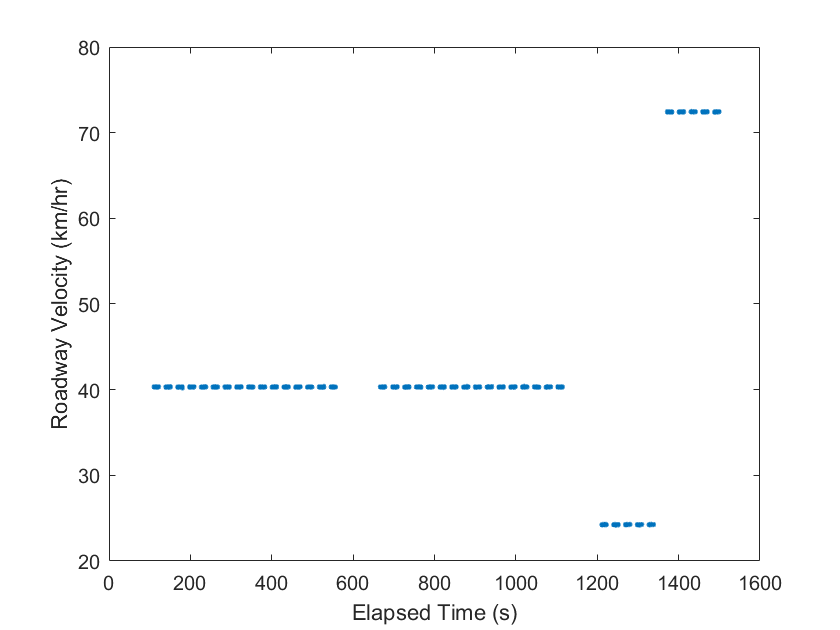

figure(1)
plot(ET, V, '.');
xlabel('Elapsed Time (s)'); ylabel('Roadway Velocity (km/hr)');

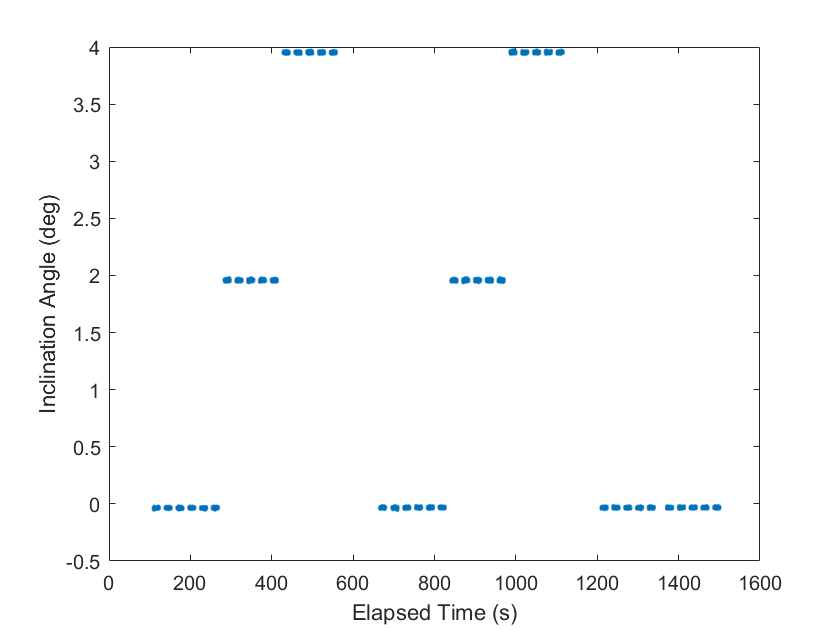

figure(2)
plot(ET, IA, '.');
xlabel('Elapsed Time (s)'); ylabel('Inclination Angle (deg)');

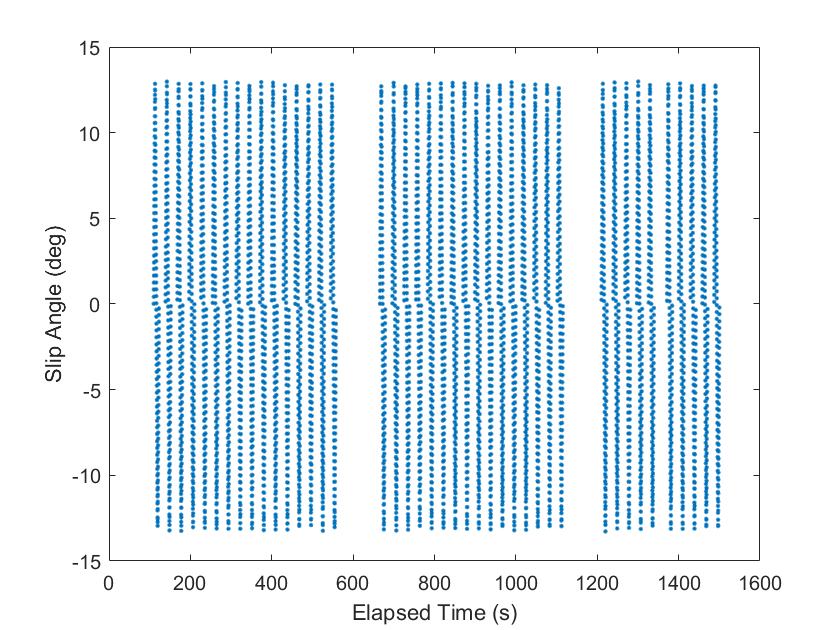

figure(3)
plot(ET, SA, '.');
xlabel('Elapsed Time (s)'); ylabel('Slip Angle (deg)');

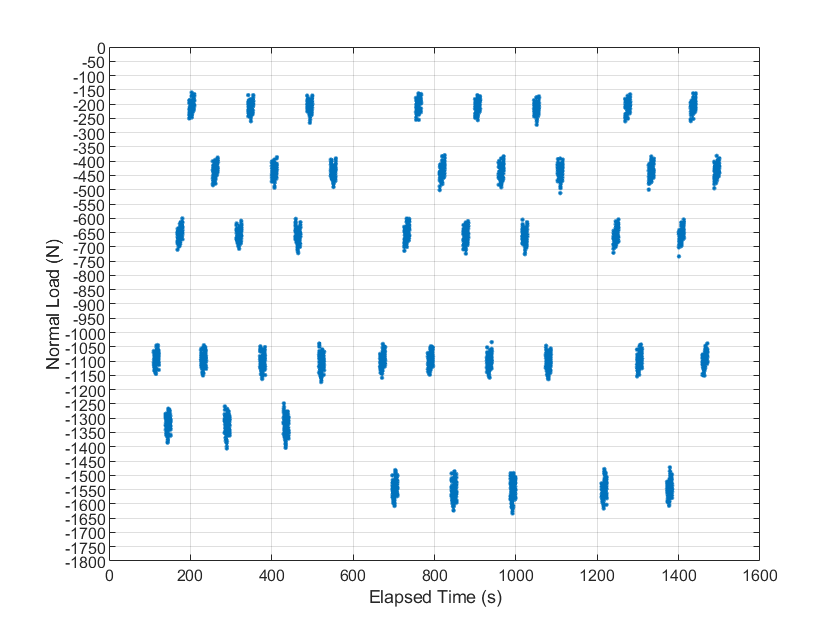

figure(4)
plot(ET, FZ, '.');
xlabel('Elapsed Time (s)'); ylabel('Normal Load (N)');
set(gca, 'ytick', -1800:50:0, 'FontSize', 8);
grid on;

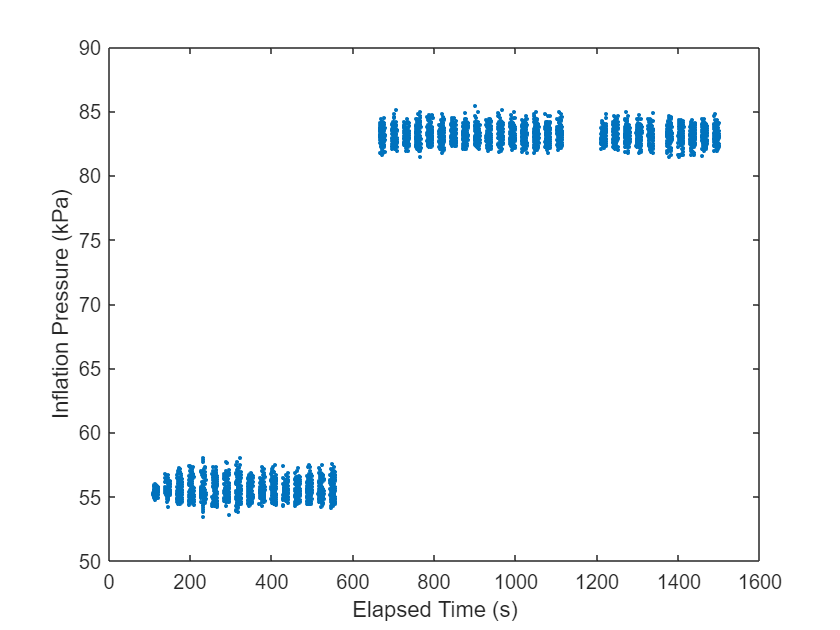

figure(5)
plot(ET, P, '.');
xlabel('Elapsed Time (s)'); ylabel('Inflation Pressure (kPa)');

% Data preprocessing (for questions 1-5, only use the data at 0 deg. inclination angle, 12 psi inflation pressure and 25 mph roadway speed)
IA_desired = 0; % deg
P_desired = 12; % psi
P_desired = P_desired * 6.895; % kPa
V_desired = 25; % mph
V_desired = V_desired * 1.609344; % kmph
ET_desired_indices = [];

for i = 1:length(ET)
    if abs(IA(i)-IA_desired)<=0.5 && abs(P(i)-P_desired)<=5 && abs(V(i)-V_desired)<=1
        ET_desired_indices(end+1) = i;
    end
end
% Visually observing the data, we can see that there are 6 different normal load (FZ) values
FZ_50_indices = find((abs(FZ) >= min(abs(FZ))) & (abs(FZ) <= 300)); % FZ ~ 50 lb
FZ_100_indices = find((abs(FZ) > 300) & (abs(FZ) <= 550)); % FZ ~ 100 lb
FZ_150_indices = find((abs(FZ) > 550) & (abs(FZ) <= 750)); % FZ ~ 150 lb
% No data for FZ ~ 200 lb
FZ_250_indices = find((abs(FZ) > 1000) & (abs(FZ) <= 1200)); % FZ ~ 250 lb
FZ_300_indices = find((abs(FZ) > 1200) & (abs(FZ) <= 1450)); % FZ ~ 300 lb
FZ_350_indices = find((abs(FZ) > 1450) & (abs(FZ) <= max(abs(FZ)))); % FZ ~ 350 lb

1. Plot Lateral Force vs. Slip Angle for each Normal Load. Plots should be similar to those on pages 76-80 of RCVD. (You may place all curves on one plot if each curve is properly identified.) Submit the plot.

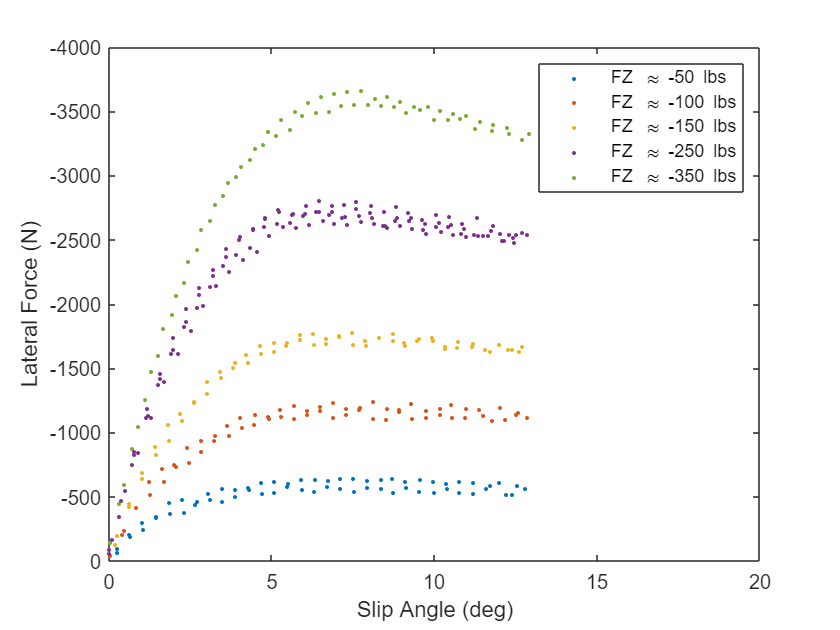

% Segregate FY and SA data based on corresponding FZ values
[FZ_50_desired,FZ_100_desired,FZ_150_desired,FZ_250_desired,FZ_300_desired,FZ_350_desired] = deal([]);
[FY_50,FY_100,FY_150,FY_250,FY_300,FY_350] = deal([]);
[SA_50,SA_100,SA_150,SA_250,SA_300,SA_350] = deal([]);
for i = 1:length(ET_desired_indices)
    if ismember(ET_desired_indices(i), FZ_50_indices)
        FZ_50_desired(end+1) = FZ(ET_desired_indices(i));
        FY_50(end+1) = FY(ET_desired_indices(i));
        SA_50(end+1) = SA(ET_desired_indices(i));
    elseif ismember(ET_desired_indices(i), FZ_100_indices)
        FZ_100_desired(end+1) = FZ(ET_desired_indices(i));
        FY_100(end+1) = FY(ET_desired_indices(i));
        SA_100(end+1) = SA(ET_desired_indices(i));
    elseif ismember(ET_desired_indices(i), FZ_150_indices)
        FZ_150_desired(end+1) = FZ(ET_desired_indices(i));
        FY_150(end+1) = FY(ET_desired_indices(i));
        SA_150(end+1) = SA(ET_desired_indices(i));
    elseif ismember(ET_desired_indices(i), FZ_250_indices)
        FZ_250_desired(end+1) = FZ(ET_desired_indices(i));
        FY_250(end+1) = FY(ET_desired_indices(i));
        SA_250(end+1) = SA(ET_desired_indices(i));
    elseif ismember(ET_desired_indices(i), FZ_300_indices) % [NOTE: FZ=300 values are not in range of ET_desired_indices]
        FZ_300_desired(end+1) = FZ(ET_desired_indices(i));
        FY_300(end+1) = FY(ET_desired_indices(i));
        SA_300(end+1) = SA(ET_desired_indices(i));
    elseif ismember(ET_desired_indices(i), FZ_350_indices)
        FZ_350_desired(end+1) = FZ(ET_desired_indices(i));
        FY_350(end+1) = FY(ET_desired_indices(i));
        SA_350(end+1) = SA(ET_desired_indices(i));
    else
        fprintf("ET index does not correspond to any FZ value!")
    end
end
FZ_50 = mean(FZ_50_desired);
FZ_100 = mean(FZ_100_desired);
FZ_150 = mean(FZ_150_desired);
FZ_250 = mean(FZ_250_desired);
FZ_300 = mean(FZ_300_desired);
FZ_350 = mean(FZ_350_desired);
% Plot FY vs SA data for each FZ
figure()
plot(SA_50,FY_50, '.')
hold on
plot(SA_100,FY_100, '.')
plot(SA_150,FY_150, '.')
plot(SA_250,FY_250, '.')
plot(SA_300,FY_300, '.')
plot(SA_350,FY_350, '.')
xlabel("Slip Angle (deg)")
ylabel("Lateral Force (N)")
legend("FZ \approx -50 lbs","FZ \approx -100 lbs","FZ \approx -150 lbs","FZ \approx -250 lbs","FZ \approx -350 lbs", 'Location','NE')
set(gca, 'YDir','reverse') % Invert Y-axis to match RCVD convention
xlim([0, 20]) % Limit X-axis to 1st quadrant to match RCVD convention
ylim([-4000, 0]) % Limit (inverted) Y-axis to 1st quadrant to match RCVD convention
hold off

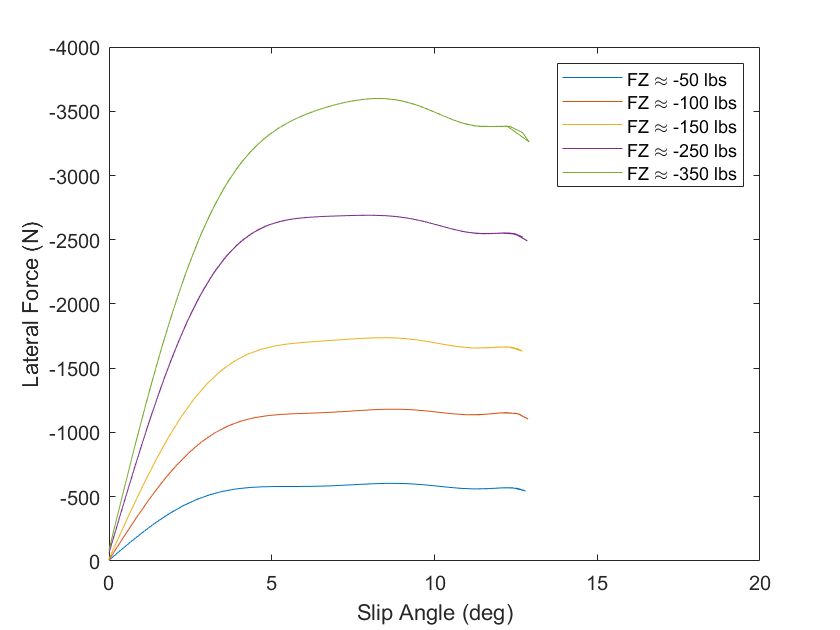

% Fit polinomials to FY vs SA data
poly_50 = polyfit(SA_50,FY_50,11);
poly_100 = polyfit(SA_100,FY_100,11);
poly_150 = polyfit(SA_150,FY_150,11);
poly_250 = polyfit(SA_250,FY_250,11);
poly_350 = polyfit(SA_350,FY_350,11);
% Plot polinomials fit to FY vs SA data
figure()
plot(SA_50,polyval(poly_50,SA_50))
hold on
plot(SA_100,polyval(poly_100,SA_100))
plot(SA_150,polyval(poly_150,SA_150))
plot(SA_250,polyval(poly_250,SA_250))
plot(SA_350,polyval(poly_350,SA_350))
xlabel("Slip Angle (deg)")
ylabel("Lateral Force (N)")
legend("FZ \approx -50 lbs","FZ \approx -100 lbs","FZ \approx -150 lbs","FZ \approx -250 lbs","FZ \approx -350 lbs", 'Location','NE')
set(gca, 'YDir','reverse') % Invert Y-axis to match RCVD convention
xlim([0, 20]) % Limit X-axis to 1st quadrant to match RCVD convention
ylim([-4000, 0]) % Limit (inverted) Y-axis to 1st quadrant to match RCVD convention
hold off

2. Determine the Cornering Stiffness of the tire at each Normal Load. Put these values in a table and plot Cornering Stiffness vs. Normal Load (one plot). Submit the table and the plot.

% Take derivatives of polinomials fit to FY vs SA data
poly_50_prime = polyder(poly_50);
poly_100_prime = polyder(poly_100);
poly_150_prime = polyder(poly_150);
poly_250_prime = polyder(poly_250);
poly_350_prime = polyder(poly_350);
% Evaluate derivatives at SA = 0 deg (this is the cornering stiffness)
c_50 = abs(polyval(poly_50_prime, 0));
c_100 = abs(polyval(poly_100_prime, 0));
c_150 = abs(polyval(poly_150_prime, 0));
c_250 = abs(polyval(poly_250_prime, 0));
c_350 = abs(polyval(poly_350_prime, 0));
% Generate table of c vs FZ
c_FZ_table = [FZ_50 FZ_100 FZ_150 FZ_250 FZ_350;
              c_50  c_100  c_150  c_250  c_350]

c_FZ_table = 1.0e+03 *

   -0.2080   -0.4351   -0.6566   -1.0972   -1.5459
    0.2155    0.3964    0.5612    0.8601    1.0356


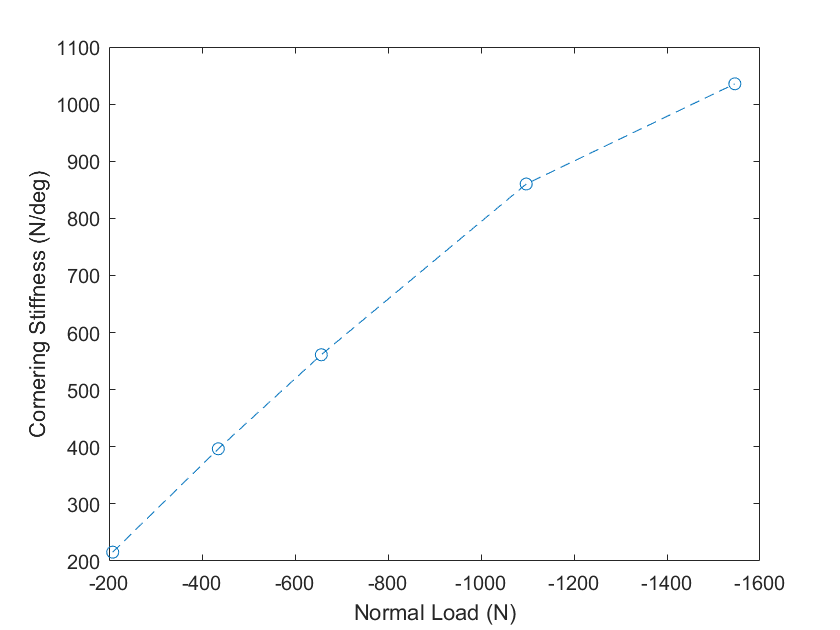

% Plot c vs FZ
figure()
plot(c_FZ_table(1,:), c_FZ_table(2,:), '--o')
xlabel("Normal Load (N)")
ylabel("Cornering Stiffness (N/deg)")
set(gca, 'XDir','reverse') % Invert X-axis to match RCVD convention

3. Determine the Friction Coefficient of the tire at each Normal Load in a left hand turn. Put these values in a table and plot Friction Coefficient vs. Normal Load (one plot). Submit the table and the plot.

% Compute u for different FZ values
% Left turn corresponds to +SA values (acc. to SAE convention)
% SA and FY have opp. signs, hence left turn corresponds to -FY
% Change to `u_lbs = abs(max(FY_lbs)/FZ_lbs)` for right turn
u_50 = abs(min(FY_50)/FZ_50);
u_100 = abs(min(FY_100)/FZ_100);
u_150 = abs(min(FY_150)/FZ_150);
u_250 = abs(min(FY_250)/FZ_250);
u_350 = abs(min(FY_350)/FZ_350);
% Generate table of u vs FZ
u_FZ_table = [FZ_50 FZ_100 FZ_150 FZ_250 FZ_350;
              u_50  u_100  u_150  u_250  u_350]

u_FZ_table = 1.0e+03 *

   -0.2080   -0.4351   -0.6566   -1.0972   -1.5459
    0.0031    0.0029    0.0027    0.0026    0.0024


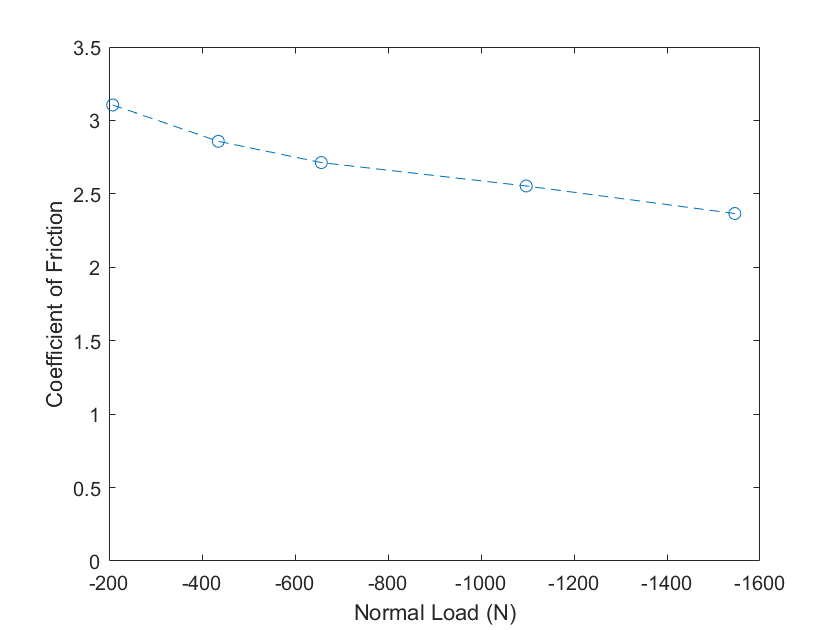

% Plot u vs FZ
figure()
plot(u_FZ_table(1,:), u_FZ_table(2,:), '--o')
xlabel("Normal Load (N)")
ylabel("Coefficient of Friction")
ylim([0,3.5])
set(gca, 'XDir','reverse') % Invert X-axis to match RCVD convention

4. Plot Aligning Torque vs. Slip Angle for each Normal Load. Plots should be somewhat similar to that on page 30 of RCVD. (You may place all curves on one plot if each curve is properly labeled.) Submit the plot.

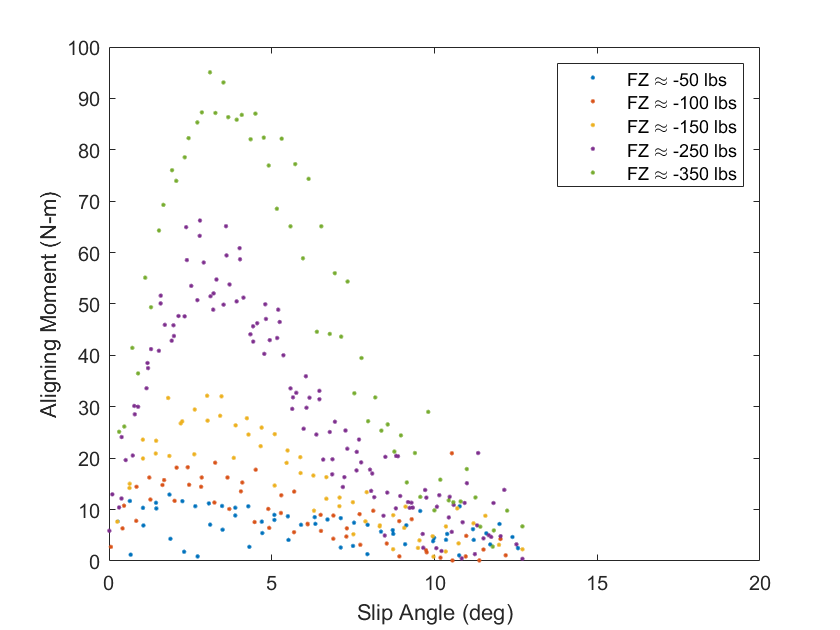

% Segregate MZ data based on corresponding FZ values
[MZ_50,MZ_100,MZ_150,MZ_250,MZ_300,MZ_350] = deal([]);
for i = 1:length(ET_desired_indices)
    if ismember(ET_desired_indices(i), FZ_50_indices)
        MZ_50(end+1) = MZ(ET_desired_indices(i));
    elseif ismember(ET_desired_indices(i), FZ_100_indices)
        MZ_100(end+1) = MZ(ET_desired_indices(i));
    elseif ismember(ET_desired_indices(i), FZ_150_indices)
        MZ_150(end+1) = MZ(ET_desired_indices(i));
    elseif ismember(ET_desired_indices(i), FZ_250_indices)
        MZ_250(end+1) = MZ(ET_desired_indices(i));
    elseif ismember(ET_desired_indices(i), FZ_300_indices) % [NOTE: FZ=300 values are not in range of ET_desired_indices]
        MZ_300(end+1) = MZ(ET_desired_indices(i));
    elseif ismember(ET_desired_indices(i), FZ_350_indices)
        MZ_350(end+1) = MZ(ET_desired_indices(i));
    else
        fprintf("ET index does not correspond to any FZ value!")
    end
end
% Plot MZ vs SA data for each FZ
figure()
plot(SA_50,MZ_50, '.')
hold on
plot(SA_100,MZ_100, '.')
plot(SA_150,MZ_150, '.')
plot(SA_250,MZ_250, '.')
plot(SA_300,MZ_300, '.')
plot(SA_350,MZ_350, '.')
xlabel("Slip Angle (deg)")
ylabel("Aligning Moment (N-m)")
legend("FZ \approx -50 lbs","FZ \approx -100 lbs","FZ \approx -150 lbs","FZ \approx -250 lbs","FZ \approx -350 lbs", 'Location','NE')
xlim([0, 20]) % Limit X-axis to 1st quadrant to match RCVD convention
ylim([0, 100]) % Limit Y-axis to 1st quadrant to match RCVD convention
hold off

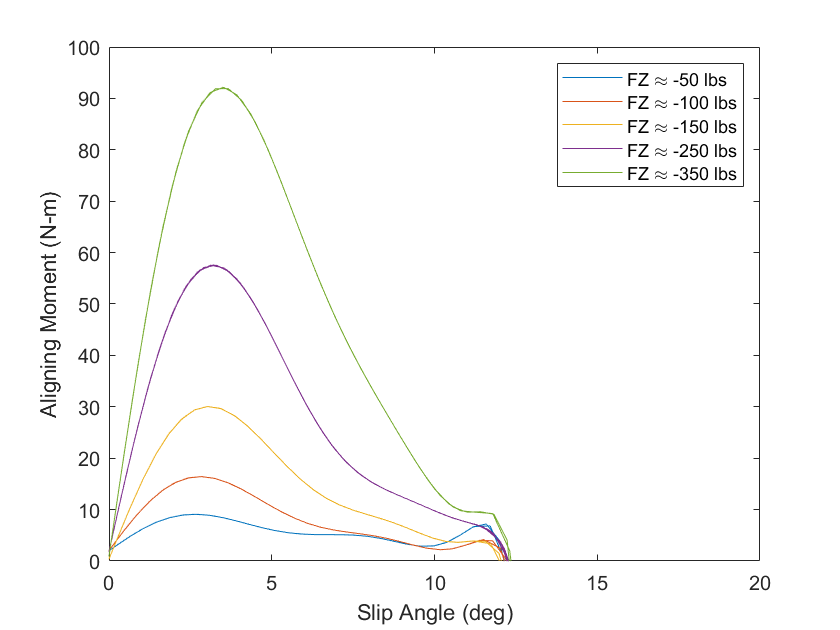

% Fit polinomials to MZ vs SA data
poly_50 = polyfit(SA_50,MZ_50,11);
poly_100 = polyfit(SA_100,MZ_100,11);
poly_150 = polyfit(SA_150,MZ_150,11);
poly_250 = polyfit(SA_250,MZ_250,11);
poly_350 = polyfit(SA_350,MZ_350,11);
% Plot polinomials fit to FY vs SA data
figure()
plot(SA_50,polyval(poly_50,SA_50))
hold on
plot(SA_100,polyval(poly_100,SA_100))
plot(SA_150,polyval(poly_150,SA_150))
plot(SA_250,polyval(poly_250,SA_250))
plot(SA_350,polyval(poly_350,SA_350))
xlabel("Slip Angle (deg)")
ylabel("Aligning Moment (N-m)")
legend("FZ \approx -50 lbs","FZ \approx -100 lbs","FZ \approx -150 lbs","FZ \approx -250 lbs","FZ \approx -350 lbs", 'Location','NE')
xlim([0, 20]) % Limit X-axis to 1st quadrant to match RCVD convention
ylim([0, 100]) % Limit Y-axis to 1st quadrant to match RCVD convention
hold off

5. The first approximation in modeling the vertical behavior of a tire is to consider the tire simply as a spring. Determine the Vertical Spring Rate of the tire at zero Slip Angle, zero Inclination Angle and zero Lateral Force. To do this, begin by plotting Normal Load vs. Loaded Radius at this condition. The slope of this curve is the tire vertical spring rate. What is the spring rate at 200 lb Normal Load? Submit your plot and the value at 200 lb.

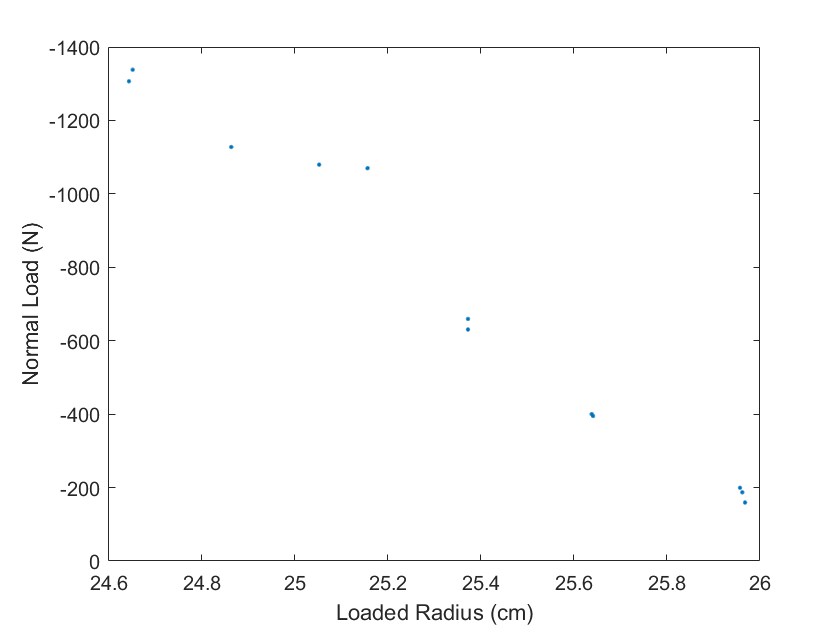

% Data preprocessing (for questions 1-5, only use the data at 0 deg. inclination angle, 12 psi inflation pressure and 25 mph roadway speed)
% In addition to the above, for question 5, only use the data at 0 deg. slip angle and 0 N lateral force
SA_desired = 0; % deg
FY_desired = 0; % N
ET_desired_indices_new = [];
for i = 1:length(ET_desired_indices)
    if abs(SA(i)-SA_desired)<0.5 && abs(FY(i)-FY_desired)<=100
        ET_desired_indices_new(end+1) = i;
    end
end
% Plot FZ vs RL data
figure()
plot(RL(ET_desired_indices_new),FZ(ET_desired_indices_new), '.')
xlabel("Loaded Radius (cm)")
ylabel("Normal Load (N)")
set(gca, 'YDir','reverse') % Invert Y-axis to match RCVD convention

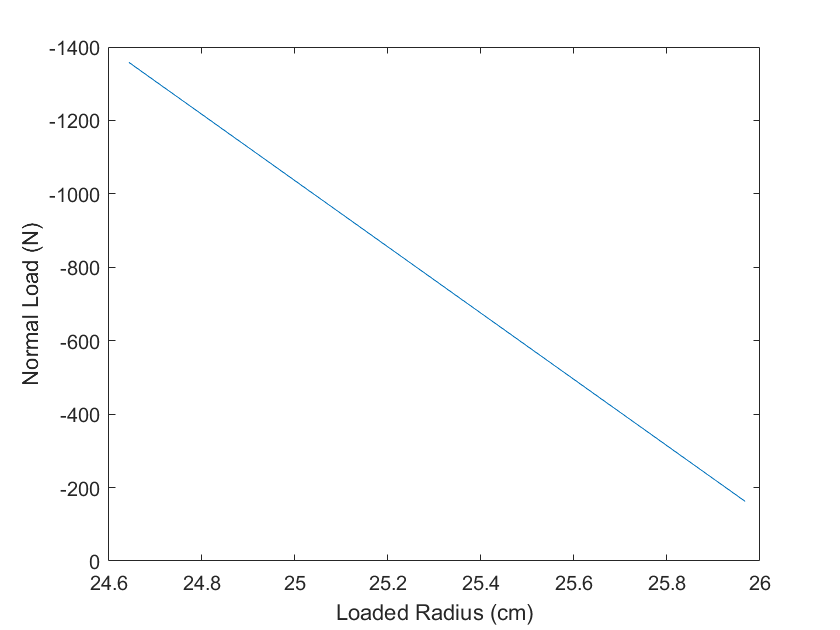

% Fit polinomial to FZ vs RL data (fit a straight line since w.k.t. spring exhibits linear dynamics)
poly_FZ_RL = polyfit(RL(ET_desired_indices_new),FZ(ET_desired_indices_new),1);
% Plot polinomial fit to FZ vs RL data
figure()
plot(RL(ET_desired_indices_new),polyval(poly_FZ_RL,RL(ET_desired_indices_new)))
xlabel("Loaded Radius (cm)")
ylabel("Normal Load (N)")
set(gca, 'YDir','reverse') % Invert Y-axis to match RCVD convention

% Slope of line fit to FZ vs RL data is the vertical spring rate
% Since slope of a line is constant, it will be the same for all loads
spring_rate = polyder(poly_FZ_RL);
fprintf("Vertical spring rate of tire at 200 lbs load is %.4f N/cm", spring_rate)

Vertical spring rate of tire at 200 lbs load is 902.2381 N/cm